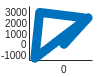

waypoints = [0 0 0; 5000 2500 15; -6000 -1300 10; -5000 3000 1; 4000 2500 0];

max_hor_vel = 25;
max_vert_vel = 1.5;
max_hor_accel = 2.5;
max_vert_accel = 1;
landing_rod = 2;

refresh_rate = 4;
time_delta = 1 / refresh_rate;

cnt = 1;

posx = zeros(1,10000);
posy = zeros(1,10000);
posz = zeros(1,10000);
velx = zeros(1,10000);
vely = zeros(1,10000);
velz = zeros(1,10000);

for i=1:length(waypoints)
    
    if i == 1
        x1 = waypoints(1, 1);
        y1 = waypoints(1, 2);
        z1 = waypoints(1, 3);
        state = 'takeoff';
        posx(1) = x1;
        posy(1) = y1;
        posz(1) = z1;

        vx = 0;
        vy = 0;
        vz = 0;

        continue;
    end
    
    x2 = waypoints(i, 1);
    y2 = waypoints(i, 2);
    z2 = waypoints(i, 3);

    x_mov = x2 > x1;
    y_mov = y2 > y1;
    z_mov = z2 > z1;

    if i == length(waypoints)
        state = 'landing-prep';
    end

    alive = true;
    while alive      
        cnt = cnt + 1;
    
        heading = atan2(x2 - x1, y2 - y1);
        if heading < 0
            heading = heading + 2 * pi;
        end
        
        current_velocity = sqrt( vx^2 + vy^2 + vz^2 );
        current_velocity = current_velocity + max_hor_accel * time_delta;
        if current_velocity > max_hor_vel
            current_velocity = max_hor_vel;
        end
    
        vx = current_velocity * sin(heading);
        vy = current_velocity * cos(heading);
        if strcmp(state, 'takeoff')
            vz = vz + max_vert_accel * time_delta;
            if vz > max_vert_vel
                vz = max_vert_vel;
            end
            z1 = z1 + vz * time_delta;
            if z1 >= z2
                z1 = z2;
                vz = 0;
                state = 'cruise';
            end
        end
        if strcmp(state, 'landing-prep')
            distance_dest = sqrt((x2-x1)^2 + (y2-y1)^2);
            time_to_dest = distance_dest / current_velocity;
            if (z1-z2) / landing_rod >= time_to_dest
                state = 'landing';
            end
        end
        if strcmp(state, 'landing')
            vz = -landing_rod;
            z1 = z1 + vz * time_delta;
            if z1 < z2
                z1 = z2;
            end
        end
        if strcmp(state, 'cruise')
            if z_mov
                vz = vz + max_vert_accel * time_delta;
                if vz > max_vert_vel
                    vz = max_vert_vel;
                end
                z1 = z1 + vz * time_delta;
                if z1 >= z2
                    z1 = z2;
                    vz = 0;
                end
            else
                vz = vz - max_vert_accel * time_delta;
                if vz < -max_vert_vel
                    vz = -max_vert_vel;
                end
                z1 = z1 + vz * time_delta;
                if z1 <= z2
                    z1 = z2;
                    vz = 0;
                end
            end
        end
    
        x1 = x1 + vx * time_delta;
        y1 = y1 + vy * time_delta;
       
        x_arr = false;
        y_arr = false;
        z_arr = false;
        if x_mov
            if x1 >= x2
                x_arr = true;
            end
        else
            if x1 <= x2
                x_arr = true;
            end
        end

        if y_mov
            if y1 >= y2
                y_arr = true;
            end
        else
            if y1 <= y2
                y_arr = true;
            end
        end

        if z_mov
            if z1 >= z2
                z_arr = true;
            end
        else
            if z1 <= z2
                z_arr = true;
            end
        end
        
        if x_arr && y_arr && z_arr
            x1 = x2;
            y1 = y2;
            z1 = z2;
            alive = false;
        end
    
        posx(cnt) = x1;
        posy(cnt) = y1;
        posz(cnt) = z1;
        velx(cnt) = vx;
        vely(cnt) = vy;
        velz(cnt) = vz;
    end
end

posx = posx(1:cnt);
posy = posy(1:cnt);
posz = posz(1:cnt);
velx = velx(1:cnt);
vely = vely(1:cnt);
velz = velz(1:cnt);

scatter(posx, posy);
xlim([min(waypoints(:,1)) max(waypoints(:,1))] .* 1.2);
ylim([min(waypoints(:,2)) max(waypoints(:,2))] .* 1.2);

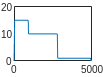


plot(posz);
ylim([min(waypoints(:,3)) max(waypoints(:,3))] .* 1.35);

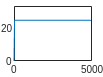


vel = sqrt(velx.^2 + vely.^2);
plot(vel);
ylim([min(vel) max(vel)] .* 1.35);

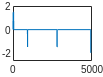


plot(velz);
ylim([min(velz) max(velz)] .* 1.35);